# Geometric Mechanics motion planning of 4-CLARI

## Geometric Functions

addpath 'Utility Functions'\ Data\;
syms a l alpha_b alpha_1 alpha_2 alpha_3 alpha_4 real
syms alpha_i real

% we shall directly use mCLARI measurements
ll = 19; % in mm
aa = 4.75/ll; % length fraction of the link to one side of the robot
bl = 2*ll*cosd(45); % the length of the robot body outline
ab0= pi/4; % nominal sprawl angle


% arbitrary leg transform
h_ib__i = [a*l*[cos(alpha_i); sin(alpha_i)]; alpha_i];

% SE(2) transforms
h_b__1b = [ l*sin(alpha_b)/2,  l*cos(alpha_b)/2, alpha_b]'; % body frame to hip frame 
h_b__2b = [-l*sin(alpha_b)/2,  l*cos(alpha_b)/2, pi-alpha_b]';
h_b__3b = [-l*sin(alpha_b)/2, -l*cos(alpha_b)/2, pi+alpha_b]';
h_b__4b = [ l*sin(alpha_b)/2, -l*cos(alpha_b)/2, -alpha_b]';

h_1b__1 = subs(h_ib__i, alpha_i, alpha_1); % hip frame to leg
h_2b__2 = subs(h_ib__i, alpha_i, alpha_2);
h_3b__3 = subs(h_ib__i, alpha_i, alpha_3);
h_4b__4 = subs(h_ib__i, alpha_i, alpha_4);

h_b__1 = simplify(seqSE2transformation([h_b__1b, h_1b__1])); % body frame to leg
h_b__2 = simplify(seqSE2transformation([h_b__2b, h_2b__2]));
h_b__3 = simplify(seqSE2transformation([h_b__3b, h_3b__3]));
h_b__4 = simplify(seqSE2transformation([h_b__4b, h_4b__4]));

h_b__12b = [              0,   l*cos(alpha_b),     alpha_b]'; % body frame to body sprawl joints
h_b__23b = [-l*sin(alpha_b),                0,  pi-alpha_b]';
h_b__34b = [              0,  -l*cos(alpha_b),  pi+alpha_b]';
h_b__41b = [ l*sin(alpha_b),                0,    -alpha_b]';

h_12b__1b = [0, -l/2, 0]'; % body sprawl joints to corresponding hip frames
h_12b__2b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l/2, 0]'] ));
h_34b__3b = [0, -l/2, 0]';
h_34b__4b = simplify(seqSE2transformation( [[0, 0, pi-2*alpha_b]', [0, l/2, 0]'] ));

h_12b__1 = simplify(seqSE2transformation([h_12b__1b, h_1b__1])); % corresponding sprawl joints to legs
h_12b__2 = simplify(seqSE2transformation([h_12b__2b, h_2b__2]));
h_34b__3 = simplify(seqSE2transformation([h_34b__3b, h_3b__3]));
h_34b__4 = simplify(seqSE2transformation([h_34b__4b, h_4b__4]));

% defining unit velocities in theta SE(2) direction-- hip actuation velocities only include rotation
theta_dot = [0, 0, 1]';

% jacobians from body to leg
J_b__1 = adj_adjinv_SE2(v2M_SE2(h_b__1), -1);
J_b__2 = adj_adjinv_SE2(v2M_SE2(h_b__2), -1);
J_b__3 = adj_adjinv_SE2(v2M_SE2(h_b__3), -1);
J_b__4 = adj_adjinv_SE2(v2M_SE2(h_b__4), -1);

% jacobians from corresponding hip joints to each leg
J_1b__1 = adj_adjinv_SE2(v2M_SE2(h_1b__1), -1);
J_2b__2 = adj_adjinv_SE2(v2M_SE2(h_2b__2), -1);
J_3b__3 = adj_adjinv_SE2(v2M_SE2(h_3b__3), -1);
J_4b__4 = adj_adjinv_SE2(v2M_SE2(h_4b__4), -1);

% jacobians from sprawl joint to legs
J_12b__1 = adj_adjinv_SE2(v2M_SE2(h_12b__1), -1);
J_12b__2 = adj_adjinv_SE2(v2M_SE2(h_12b__2), -1);
J_34b__3 = adj_adjinv_SE2(v2M_SE2(h_34b__3), -1);
J_34b__4 = adj_adjinv_SE2(v2M_SE2(h_34b__4), -1);

% define the translational velocities selection matrix
Cxy = [eye(2,2), zeros(2,1)];

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% locked case-- CLARI maintains a fixed shape -----------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% full jacobians to each leg-- first 3 columns correspond to body velocity mapping; next 4 from each hip joint
lJ_1 = [J_b__1, zeros(3,0), J_1b__1*theta_dot, zeros(3,3)];
lJ_2 = [J_b__2, zeros(3,1), J_2b__2*theta_dot, zeros(3,2)];
lJ_3 = [J_b__3, zeros(3,2), J_3b__3*theta_dot, zeros(3,1)];
lJ_4 = [J_b__4, zeros(3,3), J_4b__4*theta_dot, zeros(3,0)];

% pfaffian constraints governing the non-slip, level-2 contact states
lpfaff_12 = [Cxy*lJ_1;
            Cxy*lJ_2];
lpfaff_23 = [Cxy*lJ_2;
            Cxy*lJ_3];
lpfaff_34 = [Cxy*lJ_3;
            Cxy*lJ_4];
lpfaff_41 = [Cxy*lJ_4;
            Cxy*lJ_1];
lpfaff_13 = [Cxy*lJ_1;
            Cxy*lJ_3];
lpfaff_24 = [Cxy*lJ_2;
            Cxy*lJ_4];

% squared inter-leg distance field F
lgt_12 = Cxy*(h_b__2 - h_b__1);
lgt_23 = Cxy*(h_b__3 - h_b__2);
lgt_34 = Cxy*(h_b__4 - h_b__3);
lgt_41 = Cxy*(h_b__1 - h_b__4);
lgt_13 = Cxy*(h_b__3 - h_b__1);
lgt_24 = Cxy*(h_b__4 - h_b__2);
lF_12 = simplify(transpose(lgt_12)*lgt_12, "Steps", 10);
lF_23 = simplify(transpose(lgt_23)*lgt_23, "Steps", 10);
lF_34 = simplify(transpose(lgt_34)*lgt_34, "Steps", 10);
lF_41 = simplify(transpose(lgt_41)*lgt_41, "Steps", 10);
lF_13 = simplify(transpose(lgt_13)*lgt_13, "Steps", 10);
lF_24 = simplify(transpose(lgt_24)*lgt_24, "Steps", 10);

% normalized gradient of F-- direction of strongest slip
lgradF_12 = simplify(gradient(lF_12, [alpha_1, alpha_2])); lnorm_gradF_12 = norm(lgradF_12); lgradF_12 = simplify(lgradF_12/lnorm_gradF_12);
lgradF_23 = simplify(gradient(lF_23, [alpha_2, alpha_3])); lnorm_gradF_23 = norm(lgradF_23); lgradF_23 = simplify(lgradF_23/lnorm_gradF_23);
lgradF_34 = simplify(gradient(lF_34, [alpha_3, alpha_4])); lnorm_gradF_34 = norm(lgradF_34); lgradF_34 = simplify(lgradF_34/lnorm_gradF_34);
lgradF_41 = simplify(gradient(lF_41, [alpha_4, alpha_1])); lnorm_gradF_41 = norm(lgradF_41); lgradF_41 = simplify(lgradF_41/lnorm_gradF_41);
lgradF_13 = simplify(gradient(lF_13, [alpha_1, alpha_3])); lnorm_gradF_13 = norm(lgradF_13); lgradF_13 = simplify(lgradF_13/lnorm_gradF_13);
lgradF_24 = simplify(gradient(lF_24, [alpha_2, alpha_4])); lnorm_gradF_24 = norm(lgradF_24); lgradF_24 = simplify(lgradF_24/lnorm_gradF_24);

% get the accessible shape velocity basis                                           [nonslip, strongest slip direction]
ldelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*[lgradF_12; 0]); ldelta_alpha_12 = [ldelta_alpha_12(1:2), lgradF_12];
ldelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*[lgradF_23; 0]); ldelta_alpha_23 = [ldelta_alpha_23(1:2), lgradF_23];
ldelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*[lgradF_34; 0]); ldelta_alpha_34 = [ldelta_alpha_34(1:2), lgradF_34];
ldelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*[lgradF_41; 0]); ldelta_alpha_41 = [ldelta_alpha_41(1:2), lgradF_41];
ldelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*[lgradF_13; 0]); ldelta_alpha_13 = [ldelta_alpha_13(1:2), lgradF_13];
ldelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*[lgradF_24; 0]); ldelta_alpha_24 = [ldelta_alpha_24(1:2), lgradF_24];

% the local connections for each of these contact states-- overconstrained first 4x3 matrix needs to be pseudoinverted
lA_12 = simplify(  ( transpose(lpfaff_12(:,1:3))*lpfaff_12(:,1:3) )\transpose(lpfaff_12(:,1:3)) *lpfaff_12(:,4:end), "Steps", 20  );
lA_23 = simplify(  ( transpose(lpfaff_23(:,1:3))*lpfaff_23(:,1:3) )\transpose(lpfaff_23(:,1:3)) *lpfaff_23(:,4:end), "Steps", 20  );
lA_34 = simplify(  ( transpose(lpfaff_34(:,1:3))*lpfaff_34(:,1:3) )\transpose(lpfaff_34(:,1:3)) *lpfaff_34(:,4:end), "Steps", 20  );
lA_41 = simplify(  ( transpose(lpfaff_41(:,1:3))*lpfaff_41(:,1:3) )\transpose(lpfaff_41(:,1:3)) *lpfaff_41(:,4:end), "Steps", 20  );
lA_13 = simplify(  ( transpose(lpfaff_13(:,1:3))*lpfaff_13(:,1:3) )\transpose(lpfaff_13(:,1:3)) *lpfaff_13(:,4:end), "Steps", 20  );
lA_24 = simplify(  ( transpose(lpfaff_24(:,1:3))*lpfaff_24(:,1:3) )\transpose(lpfaff_24(:,1:3)) *lpfaff_24(:,4:end), "Steps", 20  );

% the stratified panels for each of thes contact states: connection*shape_vel
ldz_12 = simplify(lA_12*[zeros(0,1)
               ldelta_alpha_12(1);
               zeros(0,1)
               ldelta_alpha_12(2);
               zeros(2,1)], "Steps", 20);
ldz_23 = simplify(lA_23*[zeros(1,1)
               ldelta_alpha_23(1);
               zeros(0,1)
               ldelta_alpha_23(2);
               zeros(1,1)], "Steps", 20);
ldz_34 = simplify(lA_34*[zeros(2,1)
               ldelta_alpha_34(1);
               zeros(0,1)
               ldelta_alpha_34(2);
               zeros(0,1)], "Steps", 20);
ldz_41 = simplify(lA_41*[zeros(0,1)
               ldelta_alpha_41(1);
               zeros(2,1)
               ldelta_alpha_41(2);
               zeros(0,1)], "Steps", 20);
ldz_13 = simplify(lA_13*[zeros(0,1)
               ldelta_alpha_13(1);
               zeros(1,1)
               ldelta_alpha_13(2);
               zeros(1,1)], "Steps", 20);
ldz_24 = simplify(lA_24*[zeros(1,1)
               ldelta_alpha_24(1);
               zeros(1,1)
               ldelta_alpha_24(2);
               zeros(0,1)], "Steps", 20);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% unlocked case-- CLARI is free to change shape ---------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

uJ_1 = [J_b__1, J_12b__1*theta_dot, J_1b__1*theta_dot, zeros(3,3)];
uJ_2 = [J_b__2, J_12b__2*theta_dot, zeros(3,1), J_2b__2*theta_dot, zeros(3,2)];
uJ_3 = [J_b__3, J_34b__3*theta_dot, zeros(3,2), J_3b__3*theta_dot, zeros(3,1)];
uJ_4 = [J_b__4, J_34b__4*theta_dot, zeros(3,3), J_4b__4*theta_dot];

upfaff_12 = [Cxy*uJ_1;
            Cxy*uJ_2];
upfaff_23 = [Cxy*uJ_2;
            Cxy*uJ_3];
upfaff_34 = [Cxy*uJ_3;
            Cxy*uJ_4];
upfaff_41 = [Cxy*uJ_4;
            Cxy*uJ_1];
upfaff_13 = [Cxy*uJ_1;
            Cxy*uJ_3];
upfaff_24 = [Cxy*uJ_2;
            Cxy*uJ_4];

uF_12 = lF_12;
uF_23 = lF_23;
uF_34 = lF_34;
uF_41 = lF_41;
uF_13 = lF_13;
uF_24 = lF_24;

ugradF_12 = simplify(gradient(uF_12, [alpha_1, alpha_2, alpha_b])); unorm_gradF_12 = norm(ugradF_12); ugradF_12 = simplify(ugradF_12/unorm_gradF_12);
ugradF_23 = simplify(gradient(uF_23, [alpha_2, alpha_3, alpha_b])); unorm_gradF_23 = norm(ugradF_23); ugradF_23 = simplify(ugradF_23/unorm_gradF_23);
ugradF_34 = simplify(gradient(uF_34, [alpha_3, alpha_4, alpha_b])); unorm_gradF_34 = norm(ugradF_34); ugradF_34 = simplify(ugradF_34/unorm_gradF_34);
ugradF_41 = simplify(gradient(uF_41, [alpha_4, alpha_1, alpha_b])); unorm_gradF_41 = norm(ugradF_41); ugradF_41 = simplify(ugradF_41/unorm_gradF_41);
ugradF_13 = simplify(gradient(uF_13, [alpha_1, alpha_3, alpha_b])); unorm_gradF_13 = norm(ugradF_13); ugradF_13 = simplify(ugradF_13/unorm_gradF_13);
ugradF_24 = simplify(gradient(uF_24, [alpha_2, alpha_4, alpha_b])); unorm_gradF_24 = norm(ugradF_24); ugradF_24 = simplify(ugradF_24/unorm_gradF_24);

% get the accessible shape velocity basis-- both nonslip and slip directions (slip direction is the direction of shape change)
udelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*[ugradF_12(1:2); 0]); udelta_alpha_12 = [udelta_alpha_12, ugradF_12];
udelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*[ugradF_23(1:2); 0]); udelta_alpha_23 = [udelta_alpha_23, ugradF_23];
udelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*[ugradF_34(1:2); 0]); udelta_alpha_34 = [udelta_alpha_34, ugradF_34];
udelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*[ugradF_41(1:2); 0]); udelta_alpha_41 = [udelta_alpha_41, ugradF_41];
udelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*[ugradF_13(1:2); 0]); udelta_alpha_13 = [udelta_alpha_13, ugradF_13];
udelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*[ugradF_24(1:2); 0]); udelta_alpha_24 = [udelta_alpha_24, ugradF_24]; % for the whole connection

urdelta_alpha_12 = simplify(round(rot_SE2(-pi/2))*ugradF_12); urdelta_alpha_12 = [urdelta_alpha_12(1:2), ugradF_12(1:2)];
urdelta_alpha_23 = simplify(round(rot_SE2(-pi/2))*ugradF_23); urdelta_alpha_23 = [urdelta_alpha_23(1:2), ugradF_23(1:2)];
urdelta_alpha_34 = simplify(round(rot_SE2(-pi/2))*ugradF_34); urdelta_alpha_34 = [urdelta_alpha_34(1:2), ugradF_34(1:2)];
urdelta_alpha_41 = simplify(round(rot_SE2(-pi/2))*ugradF_41); urdelta_alpha_41 = [urdelta_alpha_41(1:2), ugradF_41(1:2)];
urdelta_alpha_13 = simplify(round(rot_SE2(-pi/2))*ugradF_13); urdelta_alpha_13 = [urdelta_alpha_13(1:2), ugradF_13(1:2)];
urdelta_alpha_24 = simplify(round(rot_SE2(-pi/2))*ugradF_24); urdelta_alpha_24 = [urdelta_alpha_24(1:2), ugradF_24(1:2)]; % for the reduced connection

% the local connections for each of these contact states-- overconstrained first 4x3 matrix needs to be pseudoinverted
uA_12 = simplify(  ( transpose(upfaff_12(:,1:3))*upfaff_12(:,1:3) )\transpose(upfaff_12(:,1:3)) *upfaff_12(:,4:end), "Steps", 20  );
uA_23 = simplify(  ( transpose(upfaff_23(:,1:3))*upfaff_23(:,1:3) )\transpose(upfaff_23(:,1:3)) *upfaff_23(:,4:end), "Steps", 20  );
uA_34 = simplify(  ( transpose(upfaff_34(:,1:3))*upfaff_34(:,1:3) )\transpose(upfaff_34(:,1:3)) *upfaff_34(:,4:end), "Steps", 20  );
uA_41 = simplify(  ( transpose(upfaff_41(:,1:3))*upfaff_41(:,1:3) )\transpose(upfaff_41(:,1:3)) *upfaff_41(:,4:end), "Steps", 20  );
uA_13 = simplify(  ( transpose(upfaff_13(:,1:3))*upfaff_13(:,1:3) )\transpose(upfaff_13(:,1:3)) *upfaff_13(:,4:end), "Steps", 20  );
uA_24 = simplify(  ( transpose(upfaff_24(:,1:3))*upfaff_24(:,1:3) )\transpose(upfaff_24(:,1:3)) *upfaff_24(:,4:end), "Steps", 20  );

% extract the "$alpha_b_dot" components (4th column) from each connection and replace them with the corresponding terms in limb swing velocity directions
urA_12 = reduce_2beatgait_noslip_connection(uA_12, 1, 2, ugradF_12);
urA_23 = reduce_2beatgait_noslip_connection(uA_23, 2, 3, ugradF_23);
urA_34 = reduce_2beatgait_noslip_connection(uA_34, 3, 4, ugradF_34);
urA_41 = reduce_2beatgait_noslip_connection(uA_41, 4, 1, ugradF_41);
urA_13 = reduce_2beatgait_noslip_connection(uA_13, 1, 3, ugradF_13);
urA_24 = reduce_2beatgait_noslip_connection(uA_24, 2, 4, ugradF_24);

% stratified panels for the local connections with gamma
udz_12 = simplify(uA_12*[udelta_alpha_12(3,:);
               zeros(0,2);
               udelta_alpha_12(1,:);
               zeros(0,2);
               udelta_alpha_12(2,:);
               zeros(2,2)], "Steps", 20);
udz_23 = simplify(uA_23*[udelta_alpha_23(3,:);
               zeros(1,2);
               udelta_alpha_23(1,:);
               zeros(0,2);
               udelta_alpha_23(2,:);
               zeros(1,2)], "Steps", 20);
udz_34 = simplify(uA_34*[udelta_alpha_34(3,:);
               zeros(2,2);
               udelta_alpha_34(1,:);
               zeros(0,2);
               udelta_alpha_34(2,:);
               zeros(0,2)], "Steps", 20);
udz_41 = simplify(uA_41*[udelta_alpha_41(3,:);
               zeros(0,2);
               udelta_alpha_41(1,:);
               zeros(2,2);
               udelta_alpha_41(2,:);
               zeros(0,2)], "Steps", 20);
udz_13 = simplify(uA_13*[udelta_alpha_13(3,:);
               zeros(0,2);
               udelta_alpha_13(1,:);
               zeros(1,2);
               udelta_alpha_13(2,:);
               zeros(1,2)], "Steps", 20);
udz_24 = simplify(uA_24*[udelta_alpha_24(3,:);
               zeros(1,2);
               udelta_alpha_24(1,:);
               zeros(1,2);
               udelta_alpha_24(2,:);
               zeros(0,2)], "Steps", 20);

                                            % without gamma
urdz_12 = simplify(urA_12*[zeros(0,2)
               urdelta_alpha_12(1,:);
               zeros(0,2)
               urdelta_alpha_12(2,:);
               zeros(2,2)], "Steps", 20);
urdz_23 = simplify(urA_23*[zeros(1,2)
               urdelta_alpha_23(1,:);
               zeros(0,2)
               urdelta_alpha_23(2,:);
               zeros(1,2)], "Steps", 20);
urdz_34 = simplify(urA_34*[zeros(2,2)
               urdelta_alpha_34(1,:);
               zeros(0,2)
               urdelta_alpha_34(2,:);
               zeros(0,2)], "Steps", 20);
urdz_41 = simplify(urA_41*[zeros(0,2)
               urdelta_alpha_41(1,:);
               zeros(2,2)
               urdelta_alpha_41(2,:);
               zeros(0,2)], "Steps", 20);
urdz_13 = simplify(urA_13*[zeros(0,2)
               urdelta_alpha_13(1,:);
               zeros(1,2)
               urdelta_alpha_13(2,:);
               zeros(1,2)], "Steps", 20);
urdz_24 = simplify(urA_24*[zeros(1,2)
               urdelta_alpha_24(1,:);
               zeros(1,2)
               urdelta_alpha_24(2,:);
               zeros(0,2)], "Steps", 20);

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% pack data ---------------------------------------------------------------
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Let's create functions and load all of this into a kinematics structure
clari_kin = []; clari_kin.params = []; clari_kin.sym = []; clari_kin.functions = [];

clari_kin.params.aa  = aa;
clari_kin.params.ll  = ll;
clari_kin.params.bl  = bl;
clari_kin.params.ab0 = ab0;

cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];
clari_kin.cSubmanifolds = cs;

for i = 1:4                                                                                
    % Symbolic transforms and jacobians
    clari_kin.sym. ...
        (['h_b__' num2str(i) 'b']) = eval(['h_b__' num2str(i) 'b']);
    clari_kin.sym. ...
        (['h_' num2str(i) 'b__' num2str(i)]) = eval(['h_' num2str(i) 'b__' num2str(i)]);
    clari_kin.sym. ...
        (['h_b__' num2str(i)]) = eval(['h_b__' num2str(i)]);
    clari_kin.sym. ...
        (['lJ_' num2str(i)]) = eval(['lJ_' num2str(i)]);
    clari_kin.sym. ...
        (['uJ_' num2str(i)]) = eval(['uJ_' num2str(i)]);
    % Functional transforms and jacobians
    clari_kin.functions. ...
        (['h_b__' num2str(i) 'b_f']) = matlabFunction(eval(['h_b__' num2str(i) 'b']), "Vars", [a l alpha_b]);
    clari_kin.functions. ...
        (['h_' num2str(i) 'b__' num2str(i) '_f']) = matlabFunction(eval(['h_' num2str(i) 'b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['h_b__' num2str(i) '_f']) = matlabFunction(eval(['h_b__' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['lJ_' num2str(i)]) =  matlabFunction(eval(['lJ_' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
    clari_kin.functions. ...
        (['uJ_' num2str(i)]) =  matlabFunction(eval(['uJ_' num2str(i)]),...
        "Vars", [a l alpha_b eval(['alpha_' num2str(i)])]);
end

clari_kin.sym.h_b__12b = h_b__12b;
clari_kin.sym.h_b__23b = h_b__23b;
clari_kin.sym.h_b__34b = h_b__34b;
clari_kin.sym.h_b__41b = h_b__41b;
clari_kin.sym.h_b__12b_f = matlabFunction(h_b__12b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__23b_f = matlabFunction(h_b__23b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__34b_f = matlabFunction(h_b__34b, "Vars", [a l alpha_b]);
clari_kin.sym.h_b__41b_f = matlabFunction(h_b__41b, "Vars", [a l alpha_b]);

for i = 1:size(cs,1)
    % pfaffian constraints
    clari_kin.sym.(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.sym.(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions. ...
        (['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lpfaff_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))])] ); % func
    clari_kin.functions. ...
        (['upfaff_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['upfaff_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))])] ); % func
    % scalar field F
    clari_kin.sym.(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.sym.(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions.(['lF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % func
    clari_kin.functions.(['uF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['uF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % func
    % contact submanifold information-- easier to save this elementwise
        % gradient of F in the shape space
    clari_kin.sym.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym var
    clari_kin.sym.(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.functions.(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['lnorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );                         % norm value function
    clari_kin.sym.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym var
    clari_kin.sym.(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]) = ...
        eval(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.functions.(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        matlabFunction( eval(['unorm_gradF_' num2str(cs(i,1)) num2str(cs(i,2))]), "Vars",...
        [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );                         % norm value function
    clari_kin.functions.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    for j = 1:numel(eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2))]))                                                                    % different sizes and hence done separately
        clari_kin.functions.(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['lgradF_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % compute and store func var elementwise
    end
    for j = 1:numel(eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2))]))
        clari_kin.functions.(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['ugradF_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] ); % compute and store func var elementwise
    end
        % the shape change basis
    clari_kin.sym.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]); % sym
    clari_kin.functions.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(numel(eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))])), 1); % initialize func var
    for j = 1:numel(eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))
        clari_kin.functions.(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j} = ...
            matlabFunction( eval(['ldelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ')']), "Vars",...
            [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
    end
    clari_kin.functions.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))); % initialize func var
    for j = 1:size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['udelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = ...
        cell(size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]))); % initialize func var
    for j = 1:size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urdelta_alpha_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
        % local connection
    clari_kin.sym.(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]); % reduced connection only in the unlocked case
    clari_kin.functions.(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)                                              % different matrix sizes and hence different loops
        for k = 1:size(eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['lA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['uA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]))); % reduced connection only in the unlocked case
    for j = 1:size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urA_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
        % stratified panels
    clari_kin.sym.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]);
    clari_kin.sym.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]) = eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]); % reduced connection only in the unlocked case
    clari_kin.functions.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)                                              % different matrix sizes and hence different loops
        for k = 1:size(eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['ldz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))])));
    for j = 1:size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['udz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
    clari_kin.functions.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']) = cell(size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]))); % reduced connection only in the unlocked case
    for j = 1:size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]), 1)
        for k = 1:size(eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2))]), 2)
            clari_kin.functions.(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '_f']){j, k} = ...
                matlabFunction( eval(['urdz_' num2str(cs(i,1)) num2str(cs(i,2)) '(' num2str(j) ',' num2str(k) ')']), "Vars",...
                [ a l alpha_b  eval(['alpha_' num2str(cs(i,1))])  eval(['alpha_' num2str(cs(i,2))]) ] );
        end
    end
end

% Save the data
if exist('Data\4clari.mat', 'file')
    save('Data\4clari.mat', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ... % set up in such a way that symbolic variables will be directly loaded into the workspace
        "clari_kin", "-append");
else
    save('Data\4clari.mat', "a", "l", "alpha_b", "alpha_1", "alpha_2", "alpha_3", "alpha_4", "alpha_i", ...
        "clari_kin");
end

## CLARI plotting setup

addpath 'Utility Functions'\ Data\; 
load('Data\4clari.mat');

% Let's define the body frame vector wrt to a rest frame
syms x y theta real
g_b = v2M_SE2([x, y, theta]');
rot_b = rot_SE2(theta);

% Symbolic formulae
% --------------------------------------------------------------------------------------------------------------------------------------------------------------------------

% Get the clari body and shape outlines-- shape outline is the smallest rectangle that fits the shape of CLARI
temp = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__12b, clari_kin.sym.h_b__23b, clari_kin.sym.h_b__34b, clari_kin.sym.h_b__41b, clari_kin.sym.h_b__12b], ...
    3, ones(1, 5))...
    )), 3, 3*ones(1, 5))));

body_outline_x = temp(1, :)'; body_outline_y = temp(2, :)';

temp = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__41b(1), clari_kin.sym.h_b__23b(1), clari_kin.sym.h_b__23b(1), clari_kin.sym.h_b__41b(1), clari_kin.sym.h_b__41b(1);
            clari_kin.sym.h_b__12b(2:3), clari_kin.sym.h_b__12b(2:3), clari_kin.sym.h_b__34b(2:3), clari_kin.sym.h_b__34b(2:3), clari_kin.sym.h_b__12b(2:3)], ...
            3, ones(1, 5))...
    )), 3, 3*ones(1, 5))));

shape_outline_x = temp(1, :)'; shape_outline_y = temp(2, :)';

% Get the body frame quivers

frame_x = g_b(1, 3)*ones(1, 2)'; frame_y = g_b(2, 3)*ones(1, 2)'; frame_u = g_b(1, 1:2)'; frame_v = g_b(2, 1:2)';

% legs individually
temp = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__1, clari_kin.sym.h_b__2, clari_kin.sym.h_b__3, clari_kin.sym.h_b__4], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legs_x = temp(1, :)'; legs_y = temp(2, :)'; % leg tips

temp = cell2sym(SE2_mat2vec(mat2cell(g_b*cell2sym(SE2_vec2mat(...
    mat2cell([clari_kin.sym.h_b__1b, clari_kin.sym.h_b__2b, clari_kin.sym.h_b__3b, clari_kin.sym.h_b__4b], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legsQ_x = temp(1, :)'; legsQ_y = temp(2, :)'; % to plot legs as quivers-- x and y mark the location of the base

temp = cell2sym(SE2_mat2vec(mat2cell(rot_b*cell2sym(SE2_vec2mat( ...
    mat2cell([simplify(clari_kin.sym.h_b__1 - clari_kin.sym.h_b__1b), ...
                simplify(clari_kin.sym.h_b__2 - clari_kin.sym.h_b__2b), ...
                simplify(clari_kin.sym.h_b__3 - clari_kin.sym.h_b__3b), ...
                simplify(clari_kin.sym.h_b__4 - clari_kin.sym.h_b__4b)], ...
            3, ones(1, 4))...
    )), 3, 3*ones(1, 4))));

legsQ_u = temp(1, :)'; legsQ_v = temp(2, :)'; % to plot legs as quivers-- u and v give the length of the leg "vectors" M2v_SE2

% Matlab Functions ----------------------------
body_outline_x_f = matlabFunction(body_outline_x, "Vars", [a, l, x, y, theta, alpha_b]);
body_outline_y_f = matlabFunction(body_outline_y, "Vars", [a, l, x, y, theta, alpha_b]);
shape_outline_x_f = matlabFunction(shape_outline_x, "Vars", [a, l, x, y, theta, alpha_b]);
shape_outline_y_f = matlabFunction(shape_outline_y, "Vars", [a, l, x, y, theta, alpha_b]);
frame_x_f = matlabFunction(frame_x, "Vars", [a, l, x, y, theta]);
frame_y_f = matlabFunction(frame_y, "Vars", [a, l, x, y, theta]);
frame_u_f = matlabFunction(frame_u, "Vars", [a, l, x, y, theta]);
frame_v_f = matlabFunction(frame_v, "Vars", [a, l, x, y, theta]);
legs_x_f = matlabFunction(legs_x, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legs_y_f = matlabFunction(legs_y, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_x_f = matlabFunction(legsQ_x, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_y_f = matlabFunction(legsQ_y, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_u_f = matlabFunction(legsQ_u, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);
legsQ_v_f = matlabFunction(legsQ_v, "Vars", [a, l, x, y, theta, alpha_b, alpha_1, alpha_2, alpha_3, alpha_4]);

% Save all of it to the clari kinematic structure

clari_kin.sym.body_outline_x = body_outline_x;
clari_kin.sym.body_outline_y = body_outline_y;
clari_kin.sym.shape_outline_x = shape_outline_x;
clari_kin.sym.shape_outline_y = shape_outline_y;
clari_kin.sym.frame_x = frame_x;
clari_kin.sym.frame_y = frame_y;
clari_kin.sym.frame_u = frame_u;
clari_kin.sym.frame_v = frame_v;
clari_kin.sym.legs_x = legs_x;
clari_kin.sym.legs_y = legs_y;
clari_kin.sym.legsQ_x = legsQ_x;
clari_kin.sym.legsQ_y = legsQ_y;
clari_kin.sym.legsQ_u = legsQ_u;
clari_kin.sym.legsQ_v = legsQ_v;

clari_kin.functions.body_outline_x_f = body_outline_x_f;
clari_kin.functions.body_outline_y_f = body_outline_y_f;
clari_kin.functions.shape_outline_x_f = shape_outline_x_f;      %  body and shape outline plots
clari_kin.functions.shape_outline_y_f = shape_outline_y_f;
clari_kin.functions.frame_x_f = frame_x_f;                      % body frame quivers
clari_kin.functions.frame_y_f = frame_y_f;
clari_kin.functions.frame_u_f = frame_u_f;
clari_kin.functions.frame_v_f = frame_v_f;
clari_kin.functions.legs_x_f = legs_x_f;                        % scatter leg tips
clari_kin.functions.legs_y_f = legs_y_f;
clari_kin.functions.legsQ_x_f = legsQ_x_f;                      % leg quivers
clari_kin.functions.legsQ_y_f = legsQ_y_f;
clari_kin.functions.legsQ_u_f = legsQ_u_f;
clari_kin.functions.legsQ_v_f = legsQ_v_f;

% Save the data
save('Data\4clari.mat', "clari_kin", "-append");

## A system snapshot

Here, we shall use the functions generated above to create a snapshot of the shape-locked CLARI at the nominal and extreme configurations.

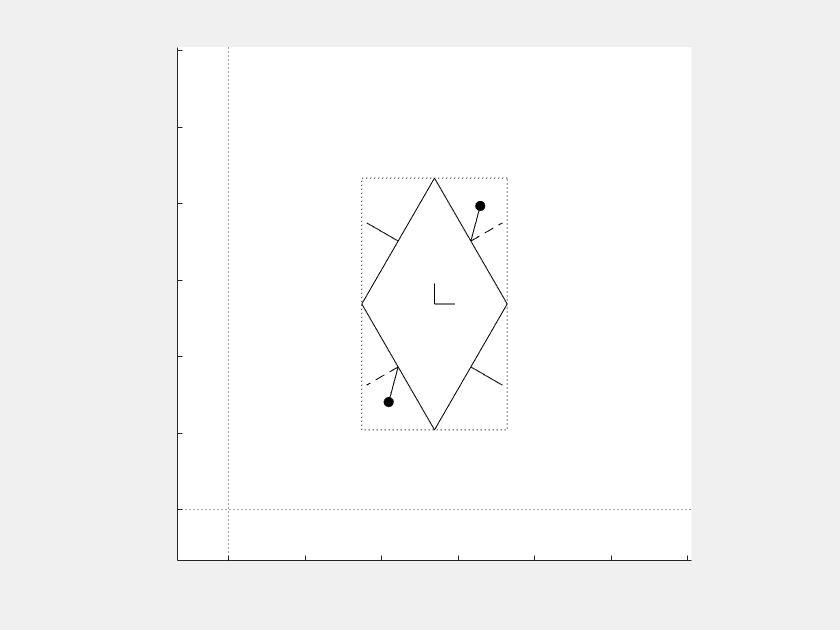

% load paths and data
addpath 'Utility Functions'\ Data\; load Data\4clari.mat;

% Setup a trajectory structure
traj = [];
traj{1} = [clari_kin.params.bl, clari_kin.params.bl, 0, pi/6, [pi/4, 0, pi/4, 0]]';
traj{2} = mat2cell(zeros(21, 1), 3*ones(1,7), 1);    % color of everything plottable
traj{3} = 5;                                         % active submanifold for this snapshot
traj{4} = nan;
traj{5} = 1;                                         % plot the body configuration
traj{6} = 1;                                         % number of frames

% Obtain the plot_trajectory struct
pltTraj = compute_pltTraj_clari(clari_kin, traj);

% define a plotting struct
pltTraj.plot_info = [];
scal = 23.5*clari_kin.params.bl/27; % /4
scaleDraw = max([diff(pltTraj.anim_lim(1:2)),diff(pltTraj.anim_lim(3:4))])/scal; % 23.5
pltTraj.plot_info.lW = 1.2/scaleDraw; pltTraj.plot_info.circS = 75/scaleDraw; pltTraj.plot_info.frame_scale = 0.10*clari_kin.params.bl;
pltTraj.plot_info.lW_r = 0.5/scaleDraw; pltTraj.plot_info.lW_s = 2.0/scaleDraw; pltTraj.plot_info.lW_b = 0.8/scaleDraw;
pltTraj.plot_info.lW_kq = 0.6/scaleDraw; pltTraj.plot_info.lW_qf = 0.8/scaleDraw;

% plot the snapshot of the robot
figure()
set(gcf,'Visible','on'); % pop-out the current figure
ax = gca; hA = plot_SE2snapshot_QLvl2_clari_NoSlip(ax, pltTraj);

## Accessible Shape Space

The reduced shape space is more restricted at a inter-leg distance because a sprawl might not exist for all possible configurations-- therefore, here we shall model the boundaries of the accessible shape as as functions of their centroid.

addpath 'Data'\ 'Utility Functions'\; load Data\4clari.mat;

% colormaps
jetDark = flipud([174,1,126; % diverging pink to blue
           221,52,151;
           247,104,161;
           250,159,181;
           116,169,207;
           54,144,192])/255;
jetDark = interp1(linspace(0,100,size(jetDark,1)), jetDark, linspace(0,100,size(jet,1))); % initialize the map based on colorbrewer
jP = sqrt(jetDark(:,1).^2 + jetDark(:,2).^2 + jetDark(:,3).^2); % power in each slice
jS = 1.1; % a proportional gain helping us shift the color levels % 0.8
jetDark = jS/max(jP)*repmat(jP,1,3).*jetDark; %%% proportional reduction with normalized power
jetDark(jetDark > 1) = 1; jetDark(jetDark < 0) = 0; % val between 0 and 1

% Set the hip limits of each limb and the sprawl limits of the body
clari_kin.params.ank = pi/2; % pi/2
clari_kin.params.ab_ank = pi/4;

% choose the contact states
csi = 1; csj = 3;

% Discretize the space
dnum = 101;
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ let's use the standard limits
ab1 = linspace(clari_kin.params.ab0-clari_kin.params.ab_ank, ...
    clari_kin.params.ab0+clari_kin.params.ab_ank, ...
    dnum); % sprawl angles
ai1 = linspace(-clari_kin.params.ank, ...
    clari_kin.params.ank, ...
    dnum);
aj1 = ai1; % limb angles
% % ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ let's use the max limits on these
% ai1 = linspace(-pi, pi, dnum);
% aj1 = ai1;                             % current shape space slice or stancing limb angles in CARTESIAN coordinates
% ab1 = linspace(0, pi/2, dnum);         % sprawl angles
[ai, aj, ab] = meshgrid(ai1, aj1, ab1); % cylindrical coords with z being the sprawl angle, and x-y plane being the swing angles of the stancing legs

% compute the squared inter-leg distance, F
Fsweep = clari_kin.functions.uF_13_f(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~ method to get the derivatives symbolically
% % compute the gradF directions in i, j, and b-directions
% gF = simplify(gradient(clari_kin.sym.uF_13, [alpha_1, alpha_3, alpha_b]), "Steps", 10);
% gFi = matlabFunction(gF(1), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% gFj = matlabFunction(gF(2), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% gFb = matlabFunction(gF(3), 'Vars', [a, l, alpha_b, alpha_1, alpha_3]);
% % compute these sweeps
% gFi_sweep = gFi(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);
% gFj_sweep = gFj(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);
% gFb_sweep = gFb(clari_kin.params.aa, clari_kin.params.ll, ab, ai, aj);

% some arrays to help computation
thetaSel = [0,0,1]; Cxy = [eye(2,2), zeros(2,1)];

% compute the maximum and minimum values of F
thetai = [0,0,1]*clari_kin.functions.(['h_b__' num2str(csi) 'b_f'])(clari_kin.params.aa, clari_kin.params.ll, ab1);
thetaj = [0,0,1]*clari_kin.functions.(['h_b__' num2str(csj) 'b_f'])(clari_kin.params.aa, clari_kin.params.ll, ab1);
ht__j2i = Cxy*( ...
    clari_kin.functions.(['h_b__' num2str(csi) 'b_f']) ...
    (clari_kin.params.aa, clari_kin.params.ll, ab1) ...
    - clari_kin.functions.(['h_b__' num2str(csj) 'b_f']) ...
    (clari_kin.params.aa, clari_kin.params.ll, ab1) ...
    );
midlink_j2i = atan2(ht__j2i(2, :),ht__j2i(1, :));
e__alpha_i = -thetai + midlink_j2i; 
e__alpha_j = -thetaj + midlink_j2i + pi;
c__alpha_i = -thetai + midlink_j2i + pi; 
c__alpha_j = -thetaj + midlink_j2i;
uF_Ubound = clari_kin.functions...
    .(['uF_' num2str(csi) num2str(csj) '_f'])...
    (clari_kin.params.aa, clari_kin.params.ll, ab1, e__alpha_i, e__alpha_j); % upper bound on F at each sprawl angle
uF_Lbound = clari_kin.functions...
    .(['uF_' num2str(csi) num2str(csj) '_f'])...
    (clari_kin.params.aa, clari_kin.params.ll, ab1, c__alpha_i, c__alpha_j); % lower bound on F at each sprawl angle
uF_range = uF_Ubound - uF_Lbound;                                            % range of the F at each sprawl angle
uF_expUbound = uF_Ubound - 0.05*uF_range; 
uF_expLbound = uF_Lbound + 0.05*uF_range;                                    % reduced upper and lower bounds-- this is just to not work near the edge cases

% Discretizing F to choose a planning regime-- find the geometry at each F value
F = linspace(min(uF_expLbound), max(uF_expUbound), dnum);                    % range of F to find points at for each sprawl angle

% Initialize storage containers
Fctrs = cell(size(F)); centr = Fctrs; FctrsP = Fctrs;

% iterate and compute the bounds
for i = 1:numel(F) % iterate over each F-level
    % compute the contours for current F-level at each sprawl angle
    for j = 1:numel(ab1)
        temp = contourc( ai1, aj1, Fsweep(:,:,j), F(i)*ones(1, 2) );
        if size(temp, 2) > 1 % if this is not true, the function couldn't find any points
            if size(temp, 2) > temp(2,1)+1
                temp = condition_contour(temp);
            end
            Fctrs{i} = [ Fctrs{i}, [ab1(j)*ones(1, temp(2,1)); temp(:,2:end)] ];
        end
    end
    % compute the centroid
    centr{i} = mean(Fctrs{i}(2:end, :), 2);
    % compute the current F-level contours wrt to the centroid in polar coordinates
    p = Fctrs{i}(2:end, :)- centr{i}; %  not taking the coordinates about the centroid anymore
    FctrsP{i}(1,:) = vecnorm(p, 2, 1);
    FctrsP{i}(2,:) = atan2(p(2,:), p(1,:));
end

% % % % % % %  rough visualization of the contours with a quick animation
% st = 1;
% figure('units','pixels','position',[100 -200 2250 1800],'Color','w')
% grid on; ax = gca;
% axis equal;
% xlim(ax, [-clari_kin.params.ank, clari_kin.params.ank]); 
% ylim(ax, [-clari_kin.params.ank, clari_kin.params.ank]);
% zlim(ax, [-clari_kin.params.ab_ank, clari_kin.params.ab_ank]);
% for idx = 1:numel(Fctrs)
%     diffF_ab = find(diff(Fctrs{idx}(1, :)));
%     for ed = 1:numel(diffF_ab)
%         if ed == 2
%             hold(ax, "on");
%         end
%         plot3(ax, Fctrs{idx}(2, st:diffF_ab(ed)), Fctrs{idx}(3, st:diffF_ab(ed)), Fctrs{idx}(1, st:diffF_ab(ed)), 'k', 'LineWidth', 1.2); % 1.2*(1+3*ed/numel(diffF_ab))
%         st = diffF_ab(ed)+1;
%     end
%     hold(ax, "off");
%     drawnow; st = 1;
% end


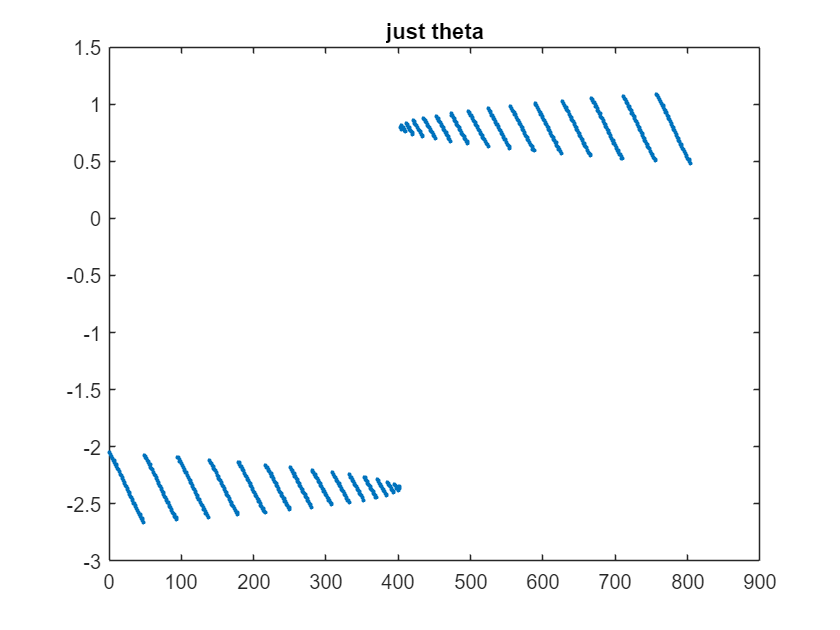

shrinkLvl = 1;
% % % % % % % % % % % % % % % %  rough boundary based accessible shape space approximation
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
idx = 1; % lowest F
plot(FctrsP{idx}(2,:), '.');
title('just theta');

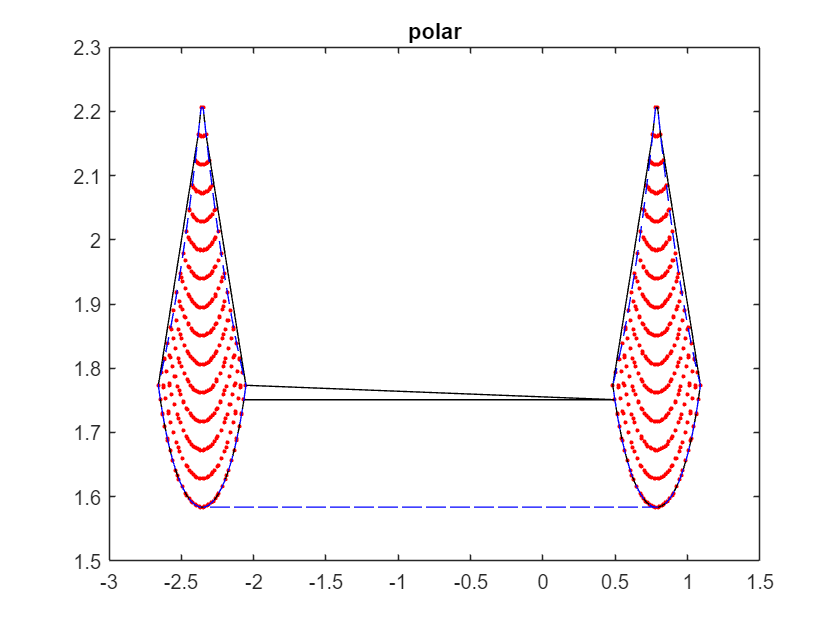

plot(FctrsP{idx}(2,:), FctrsP{idx}(1,:), 'r.'); hold on;
kP = boundary(FctrsP{idx}(2,:)', FctrsP{idx}(1,:)', shrinkLvl);
k = boundary(Fctrs{idx}(2,:)', Fctrs{idx}(3,:)', shrinkLvl);
plot(FctrsP{idx}(2,kP), FctrsP{idx}(1,kP), 'k-');
plot(FctrsP{idx}(2,k), FctrsP{idx}(1,k), 'b--');
hold off;
title('polar');

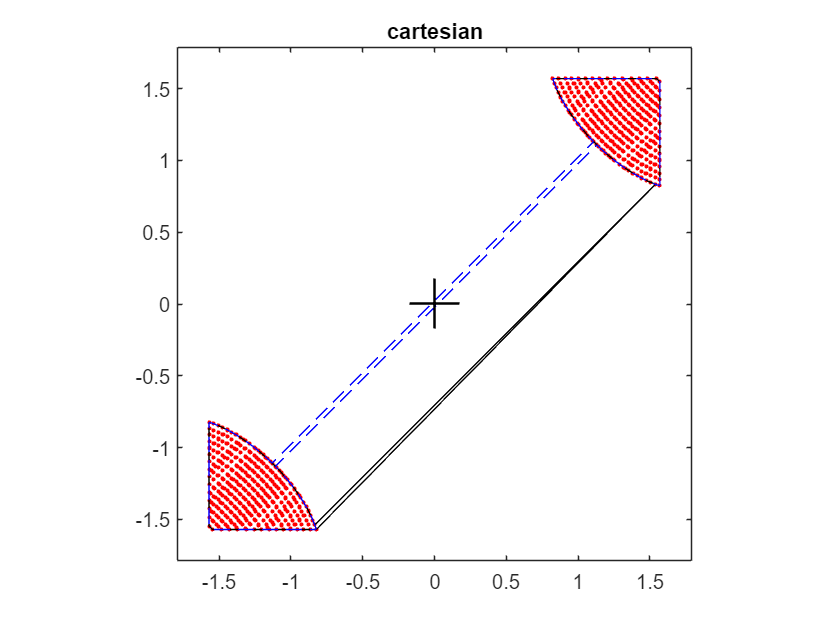

plot(Fctrs{idx}(2,:), Fctrs{idx}(3,:), 'r.'); hold on; axis equal square padded;
plot(Fctrs{idx}(2,kP), Fctrs{idx}(3,kP), 'k-');
plot(Fctrs{idx}(2,k), Fctrs{idx}(3,k), 'b--');
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
hold off;
title('cartesian');

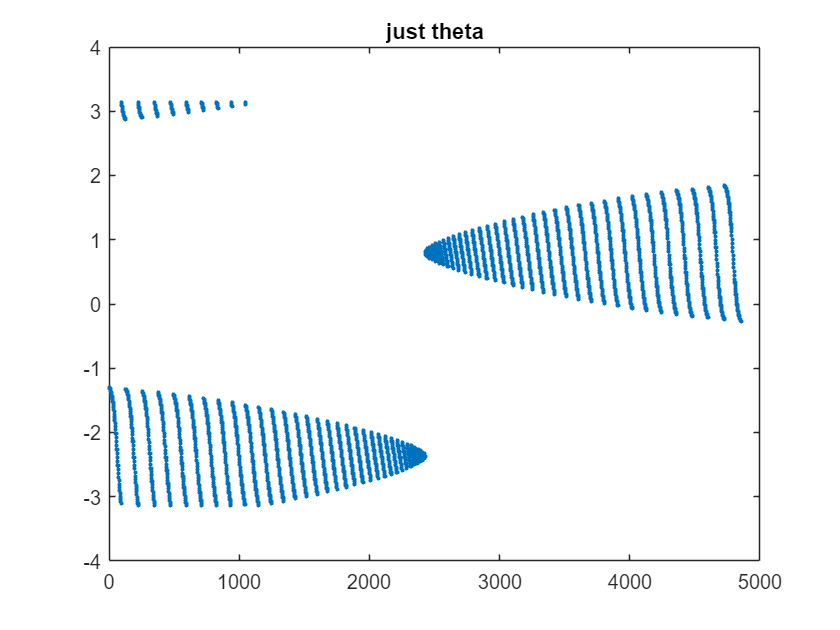

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
idx = floor(dnum/4); % quarter F
plot(FctrsP{idx}(2,:), '.');
title('just theta');

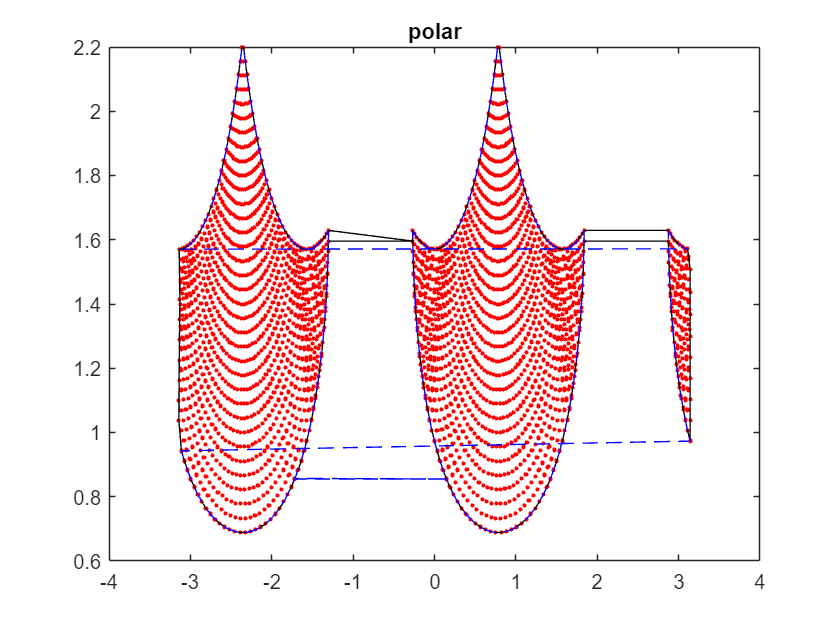

plot(FctrsP{idx}(2,:), FctrsP{idx}(1,:), 'r.'); hold on;
kP = boundary(FctrsP{idx}(2,:)', FctrsP{idx}(1,:)', shrinkLvl);
k = boundary(Fctrs{idx}(2,:)', Fctrs{idx}(3,:)', shrinkLvl);
plot(FctrsP{idx}(2,kP), FctrsP{idx}(1,kP), 'k-');
plot(FctrsP{idx}(2,k), FctrsP{idx}(1,k), 'b--');
hold off;
title('polar');

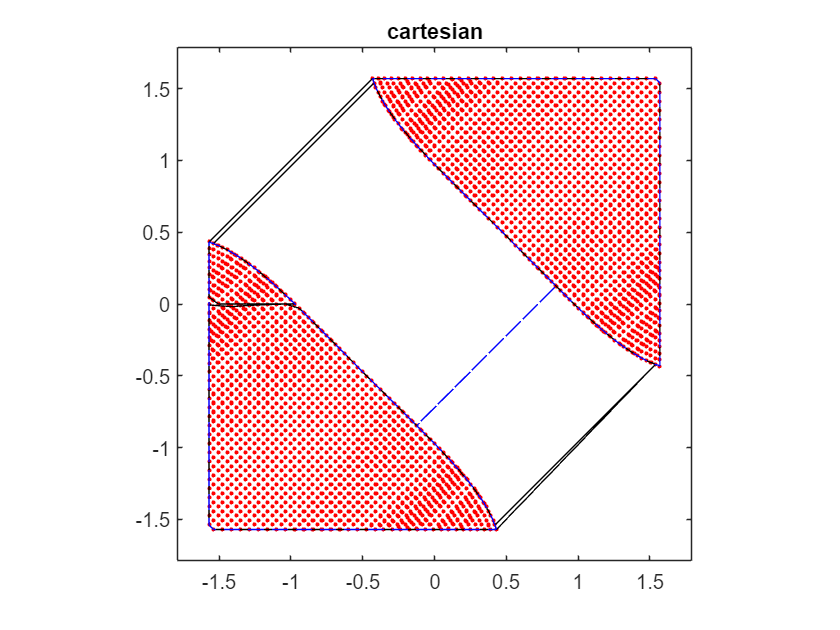

plot(Fctrs{idx}(2,:), Fctrs{idx}(3,:), 'r.'); hold on; axis equal square padded;
plot(Fctrs{idx}(2,kP), Fctrs{idx}(3,kP), 'k-');
plot(Fctrs{idx}(2,k), Fctrs{idx}(3,k), 'b--');
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
hold off;
title('cartesian');

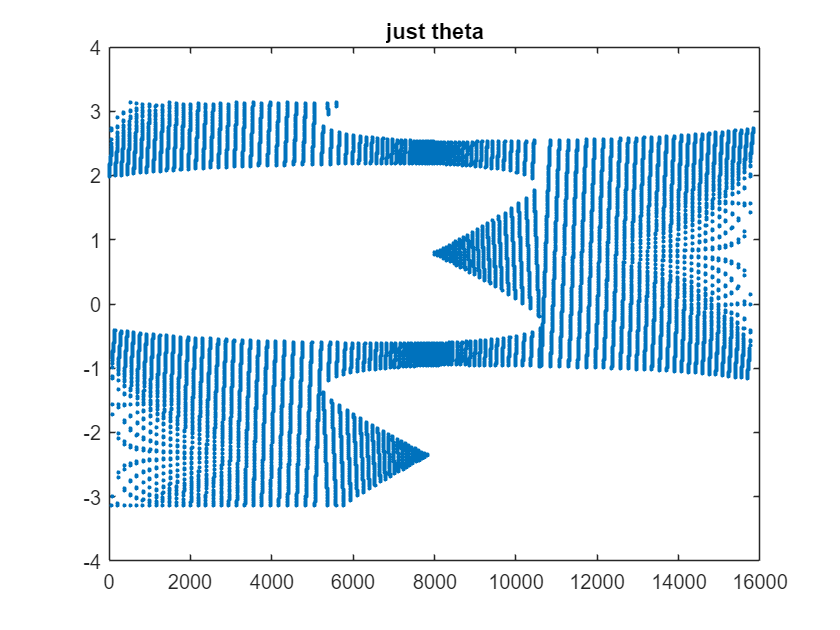

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
idx = floor(dnum/2); % mid F
plot(FctrsP{idx}(2,:), '.');
title('just theta');

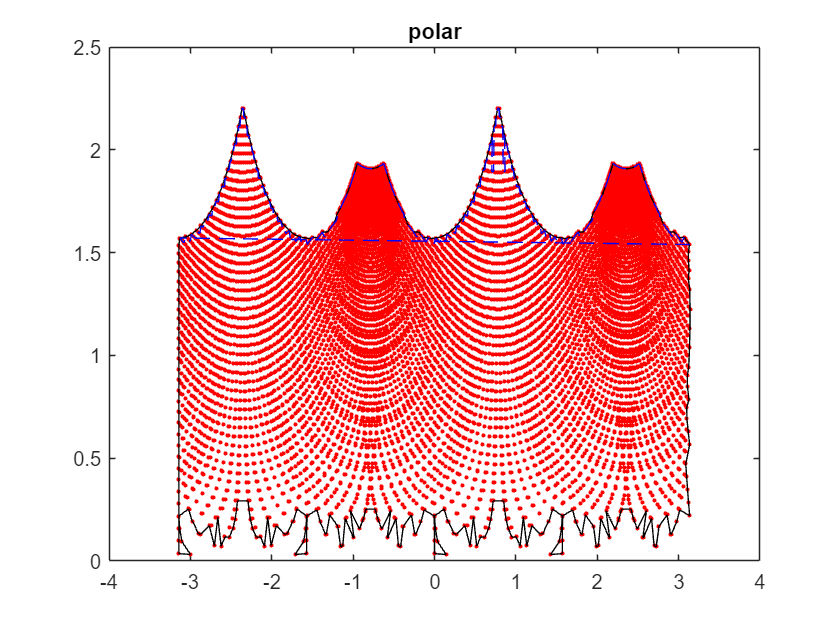

plot(FctrsP{idx}(2,:), FctrsP{idx}(1,:), 'r.'); hold on;
kP = boundary(FctrsP{idx}(2,:)', FctrsP{idx}(1,:)', shrinkLvl);
k = boundary(Fctrs{idx}(2,:)', Fctrs{idx}(3,:)', shrinkLvl);
plot(FctrsP{idx}(2,kP), FctrsP{idx}(1,kP), 'k-');
plot(FctrsP{idx}(2,k), FctrsP{idx}(1,k), 'b--');
hold off;
title('polar');

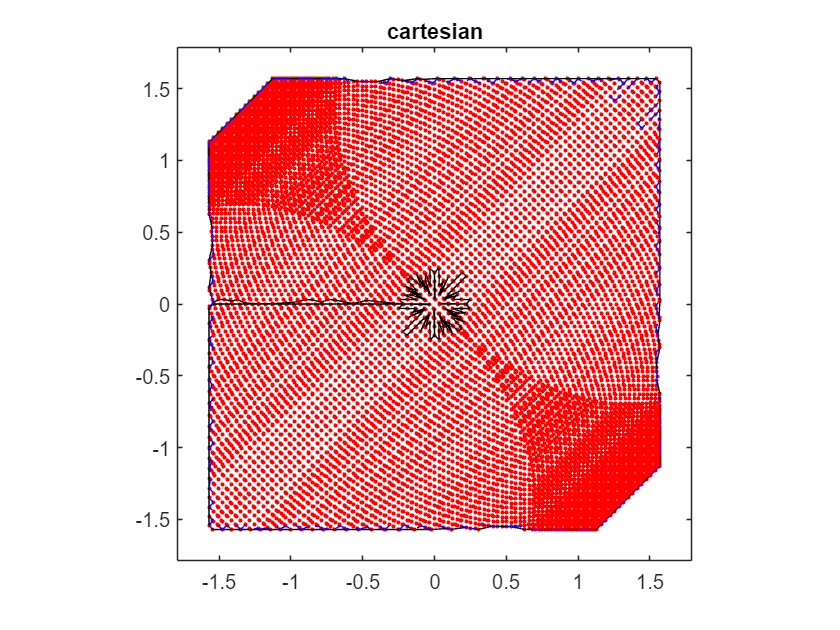

plot(Fctrs{idx}(2,:), Fctrs{idx}(3,:), 'r.'); hold on; axis equal square padded;
plot(Fctrs{idx}(2,kP), Fctrs{idx}(3,kP), 'k-');
plot(Fctrs{idx}(2,k), Fctrs{idx}(3,k), 'b--');
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
hold off;
title('cartesian');

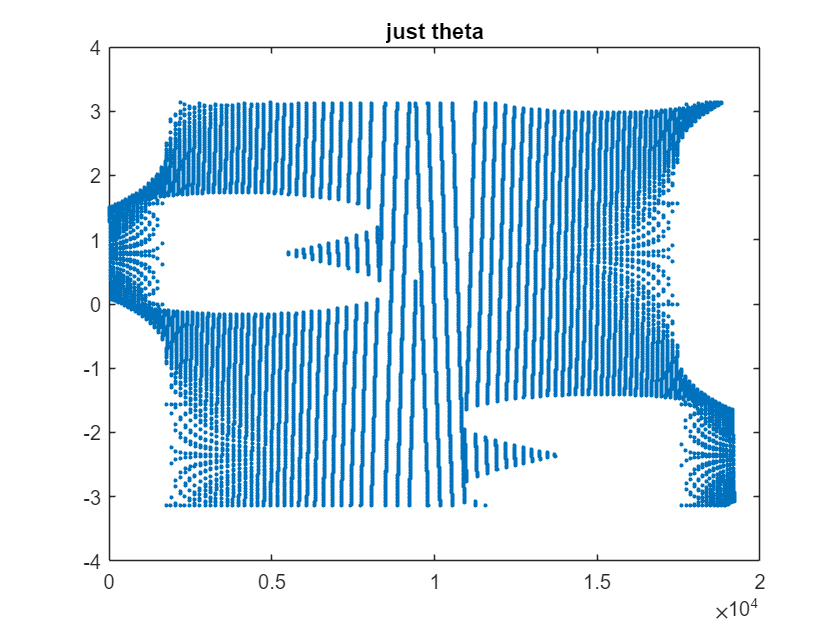

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
idx = ceil(3*dnum/4); % 3 quarters F
plot(FctrsP{idx}(2,:), '.');
title('just theta');

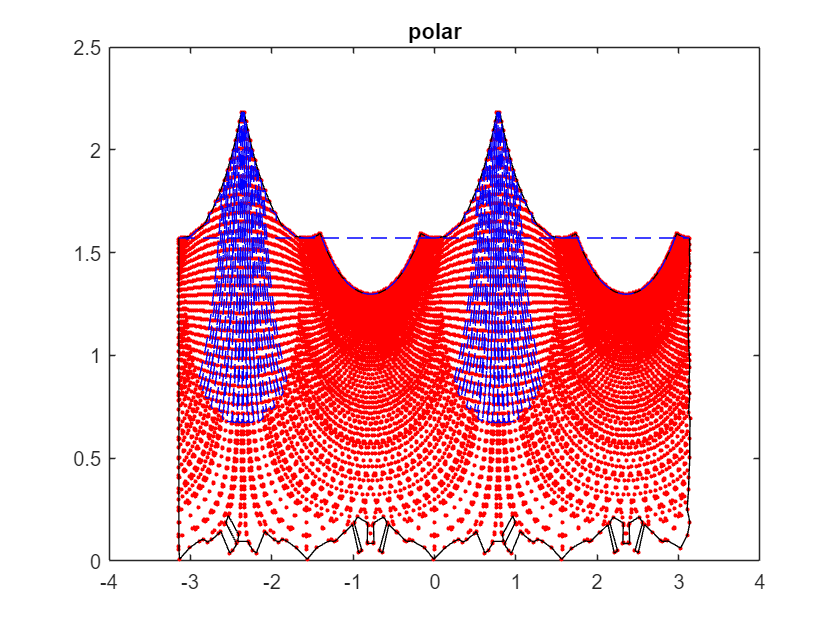

plot(FctrsP{idx}(2,:), FctrsP{idx}(1,:), 'r.'); hold on;
kP = boundary(FctrsP{idx}(2,:)', FctrsP{idx}(1,:)', shrinkLvl);
k = boundary(Fctrs{idx}(2,:)', Fctrs{idx}(3,:)', shrinkLvl);
plot(FctrsP{idx}(2,kP), FctrsP{idx}(1,kP), 'k-');
plot(FctrsP{idx}(2,k), FctrsP{idx}(1,k), 'b--');
hold off;
title('polar');

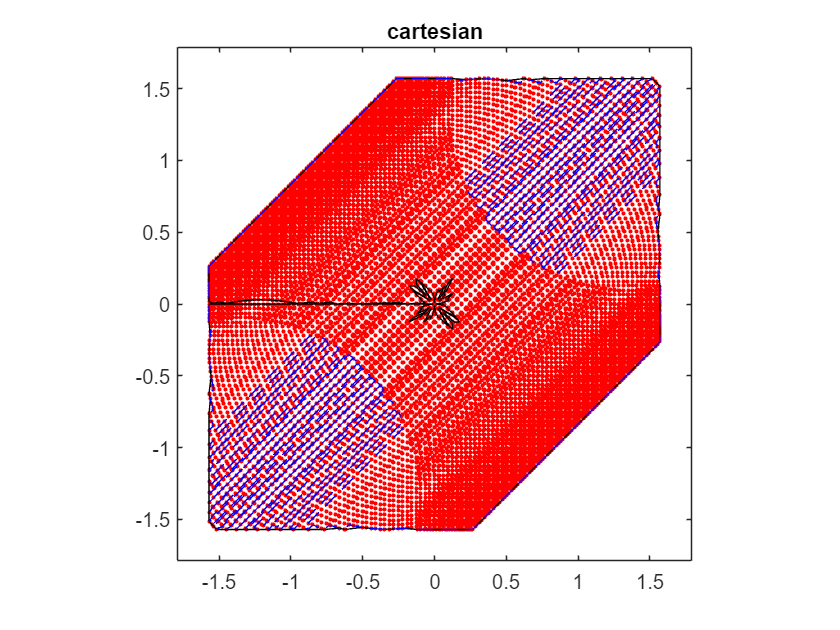

plot(Fctrs{idx}(2,:), Fctrs{idx}(3,:), 'r.'); hold on; axis equal square padded;
plot(Fctrs{idx}(2,kP), Fctrs{idx}(3,kP), 'k-');
plot(Fctrs{idx}(2,k), Fctrs{idx}(3,k), 'b--');
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
hold off;
title('cartesian');

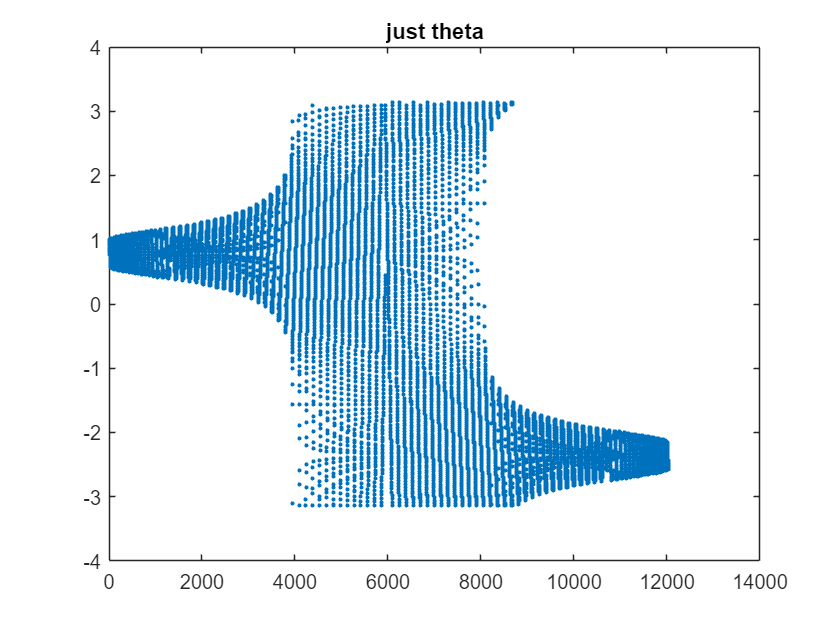

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
idx = dnum; % highest F
plot(FctrsP{idx}(2,:), '.');
title('just theta');

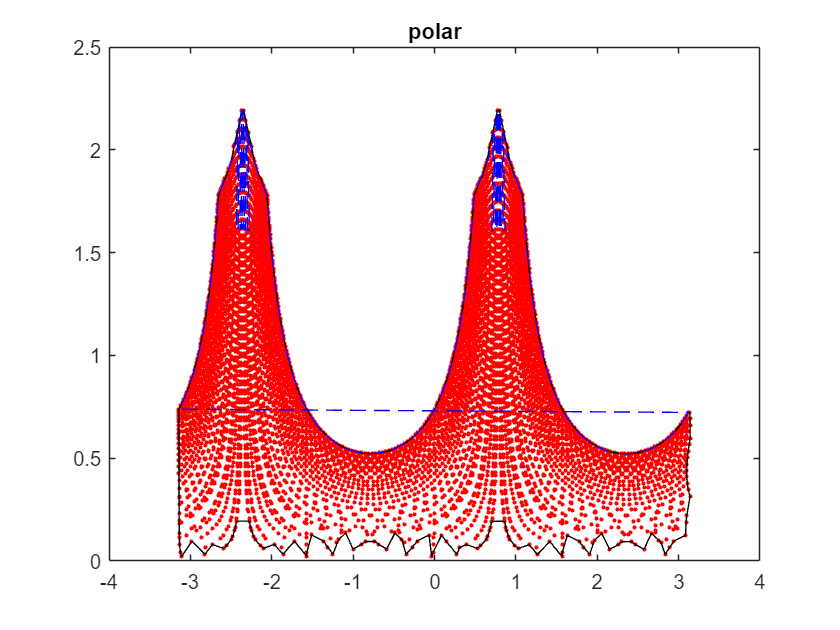

plot(FctrsP{idx}(2,:), FctrsP{idx}(1,:), 'r.'); hold on;
kP = boundary(FctrsP{idx}(2,:)', FctrsP{idx}(1,:)', shrinkLvl);
k = boundary(Fctrs{idx}(2,:)', Fctrs{idx}(3,:)', shrinkLvl);
plot(FctrsP{idx}(2,kP), FctrsP{idx}(1,kP), 'k-');
plot(FctrsP{idx}(2,k), FctrsP{idx}(1,k), 'b--');
hold off;
title('polar');

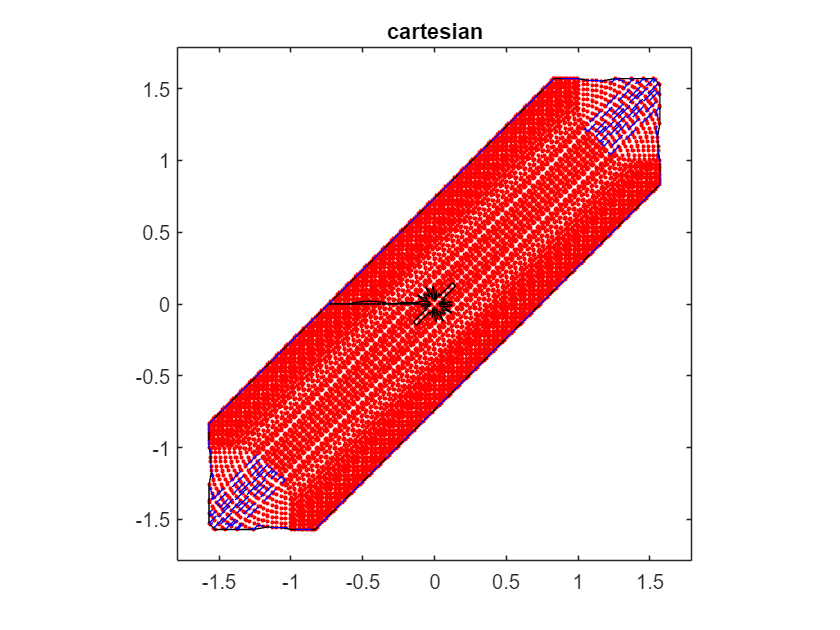

plot(Fctrs{idx}(2,:), Fctrs{idx}(3,:), 'r.'); hold on; axis equal square padded;
plot(Fctrs{idx}(2,kP), Fctrs{idx}(3,kP), 'k-');
plot(Fctrs{idx}(2,k), Fctrs{idx}(3,k), 'b--');
plot(centr{i}(1), centr{i}(2), 'k+', 'LineWidth', 1.2, MarkerSize=25);
hold off;
title('cartesian');

## Geometric Mechanics of Troting Contact Submanifolds

Obtain the geometric mechanics for quadrupedal robot with one internal, uncontrolled body DOF.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%   USER INPUTS   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Add folders to the path:
addpath 'Data'\ 'Utility Functions'\; load Data\4clari.mat;

% choose your active contact states, the kinematic fields to display, and
% robot configuration to display ------------------------------------------
cs = [1, 2;
      2, 3;
      3, 4;
      4, 1;
      1, 3;
      2, 4];

% shape-space discretization ----------------------------------------------
dnum = 101;

% plot parameters ---------------------------------------------------------
skipV = 7.5;sV = 10; skipV = round((skipV/100)*2*floor(dnum/2)); sV = round((sV/100)*2*floor(dnum/2));
cLvl = 25; cfLvl = 100; fontscale = 1.25; fA = 1.00;
plot_info = [];
plot_info.dnum = dnum; plot_info.skipV = skipV; plot_info.sV = sV; plot_info.cLvl = cLvl; plot_info.cfLvl = cfLvl;
plot_info.fontscale = fontscale; plot_info.fA = fA;

% setup the plotting details
fields = {'-A','dz'}; configs = [ones(3,1),ones(3,1)];

% Just generate for the trot contact states
clari_kin.submanifolds = [];
clari_kin.submanifolds.list = cs; clari_kin.submanifolds.fields = fields; clari_kin.submanifolds.configs = configs;
for i = [1, 3]
    % call the function and compute everthing needed
    clari_kin = qlevel2noslip_clari(clari_kin, plot_info, i); % call the function and return the results in the kinematics structure
end